# Radial Arm

clear; close all; clc;

load(fullfile(get_behavior_root(),"DataRAM.mat"));
load(fullfile(get_behavior_root(),"PostHoc.mat"));

animals = length(Data.animal);
arms = 8;
trial = length(Data.animal(3).trial); % habituation + 8 days phase 1 + 6 days phase 2
incorrect = [1,2,5,6,8];
correct = [3,4,7];
positive = [6,8,9,10];
negative = [2,3,4,5];
failed_injection = [1,7,11]; %1 = complete miss, 7 = one hem only
start_arm = nan(trial,1); %reference
start_arm(1:69) = 2;
start_arm(70:end) = 5;
days = [1:8; 9:16; 17:24; 25:32; 33:40; 41:48; 49:56; 57:64; 65:72; 73:80; 81:88; 89:96; 97:104; 105:112];


% Output variables
moved_completed = nan(trial,animals);
distance_raw = cell(trial,arms);
speed_avr = nan(trial,animals);
speed_raw = cell(trial,arms);
time_comp = nan(trial,animals);
RMtrajectory = cell(trial,animals);
comp_idx = nan(trial,animals);
latency = nan(1,arms);
total_entries = nan(trial,animals);
entry_raw = cell(trial, animals);
speed_open_field = nan(length(table2array(Data.animal(1).trial(1).name(:,1))),animals);
all_paths = cell(trial,animals);
moved_of = nan(1,animals);
occupancy_zone_of = nan(4,animals);
occupancy = cell(1,animals);
trial_length = nan(trial,animals);
entry_raw_comp = cell(trial,animals); 
%Plot specifications
colors = {'#284B5E','#BC554C'};
noLine = {'none','none'};
linew = {3,3};

## Preprocess the Data

% Keep in mind that the first 5 trials are open field and habituation
for a = 1:animals
    
    for t = 1:trial
        
        % preprocess habituation trials
        if t == 1

            open_field_raw = table2array(Data.animal(a).trial(t).name(:,13:16));
            entry_raw{1,a} = open_field_raw;
            entry_raw_comp{1,a} = open_field_raw;
            open_field_move(:,a) = table2array(Data.animal(a).trial(t).name(:,8));
            speed_open_field(:,a) = table2array(Data.animal(a).trial(t).name(:,9));
            occupancy{1,a} = [table2array(Data.animal(a).trial(1).name(:,3)),table2array(Data.animal(a).trial(1).name(:,4))];
            
        else
            time = table2array(Data.animal(a).trial(t).name(:,2));
            end_time = length(time);
            
            entries = table2array(Data.animal(a).trial(t).name(:,11:18));
            entry_raw{t,a} = entries;
            check = sum(entries);
            check_failure = find(check);
            if length(check_failure) < 1 % If detection stays in one corner the entire trial
                continue
            else
            
            distance_moved = table2array(Data.animal(a).trial(t).name(:,8));
            speed = table2array(Data.animal(a).trial(t).name(:,9)); % cm/s
            
            control_nan = sum(isnan(entries(1,:)));
            
            if control_nan > 0
                entries(1,:) = entries(2,:); 
            end
            
            %Get the full trajectory until completion
            [trajectory,completed] = traject(entries,correct);

            trial_length(t,a) = completed/25; 


            all_paths{t,a} = trajectory;

            if trajectory(1,1) == start_arm(t) 
                all_paths_errors{t,a} = trajectory(2:end);
            else
                all_paths_errors{t,a} = trajectory;
            end
            
            if t > 5
                % Distance moved to completion per trail
                m_goal = sum(distance_moved(1:completed),'omitnan'); %in cm
                moved_completed(t,a) = m_goal;
                distance_raw{t,a} = distance_moved(1:completed);
                speed_avr(t,a) = mean(speed(1:completed),'omitnan');
                speed_raw{t,a} = speed(1:completed);
                entry_raw_comp{t,a} = entries(1:completed,:);
            else
                distance_raw{t,a} = distance_moved;
                speed_avr(t,a) = mean(speed,'omitnan');
                speed_raw{t,a} = speed;
                entry_raw_comp{t,a} = entries;

            end
            
            end

        end
    end
end

## Analyze the Trajectory of the Individual Animal

% Get the number of errors made before the first treat consumption
[r,c] = size(all_paths_errors);
E1 = nan(r-5,c);
E2 = nan(r-5,c);
E3 = nan(r-5,c);
E1rm = nan(r-5,c);
E1wm = nan(r-5,c);
E2rm = nan(r-5,c);
E2wm = nan(r-5,c);
E3rm = nan(r-5,c);
E3wm = nan(r-5,c);
all_entries = nan(r-5,c);

% The first 5 trials are open field and habituation
for i = 6:r
    for j = 1:c
        path = all_paths_errors{i,j};
        if length(path) < 3
            continue
        else
            
        %raw score of errors before and after bait consumption
        [err,errm,errwm] = EntryError(path,correct,1,incorrect);
        E1(i-5,j) = err; 
        E1rm(i-5,j) = errm;
        E1wm(i-5,j) = errwm;
        
        [second_error,serm,sewm] = EntryError(path,correct,2,incorrect);
        E2(i-5,j) = second_error;
        E2rm(i-5,j) = serm;
        E2wm(i-5,j) = sewm;
        
        [third_error, thrm, thwm] = EntryError(path,correct,3,incorrect);
        E3(i-5,j) = third_error;
        E3rm(i-5,j) = thrm;
        E3wm(i-5,j) = thwm;
        
        % If I want to normalize by number of total entries (to get % correct)
        all_entries(i-5,j) = length(path);

   
        [path_count,BG,BP] = groupcounts(path);
        if length(BG)<8
            output = zeros(8,1);
            path_count_dist = zeros(8,1);
            path_count_dist(BG) = path_count;

            entry_distribution_prob{i-5,j} = output;
            entry_distribution_count{i-5,j} = path_count_dist;
        else
            entry_distribution_prob{i-5,j} = BP;
            entry_distribution_count{i-5,j} =path_count;

        end
        end
    end
end
total_error = E1 + E2 + E3;
rm_numb = E1rm + E2rm + E3rm;
wm_numb = E1wm + E2wm + E3wm;


## Quantify if there is a difference in number of perfect trials

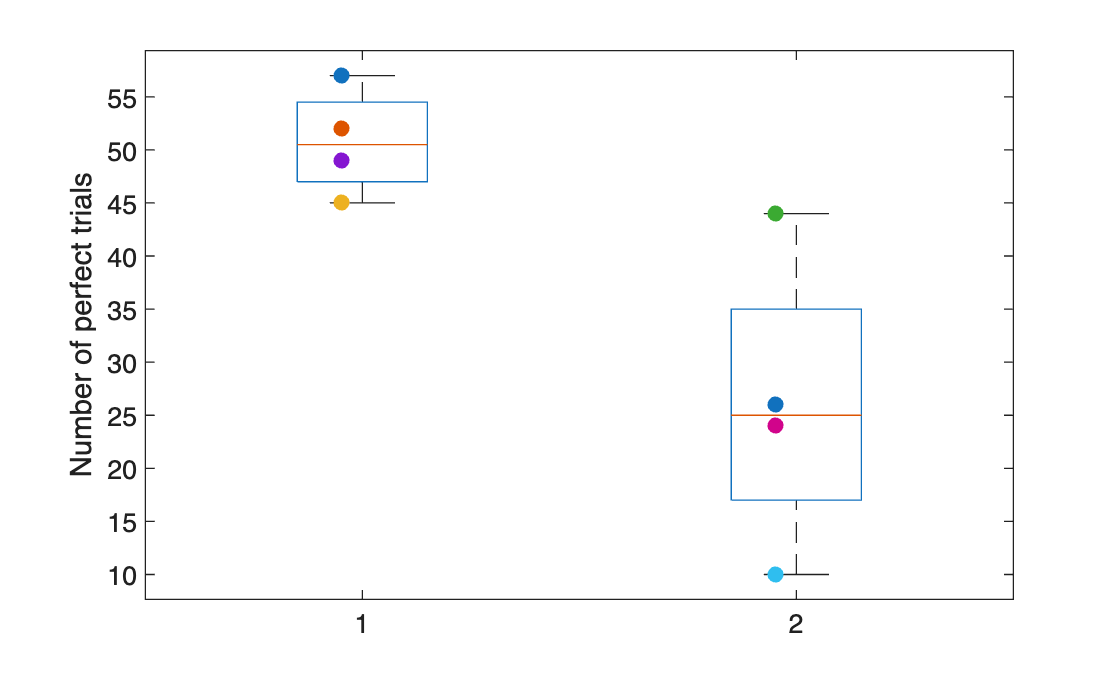

% get the number of zero elements for each animal
phase1 = 8*8;
phase2 = 8*6;
perfect_day = zeros(length(total_error));
for a = 1:animals
    
    perf(1,a) = nnz(~total_error(:,a)); %raw count 
    perf(2,a) = (nnz(~total_error(1:phase1,a)))/phase1; % all perfect trials phase 1 (row 2), normalized to number of trials
    perf(3,a) = (nnz(~total_error(phase1+1:end,a)))/phase2; % all perfect trails phase 2 (row 3), normalized
    
    % Endulge your supervisor
    perf_idx = find(~total_error(:,a));
    perfect_day(perf_idx,a) = 1;
end


perfect = [mean(perf(:,negative),2),mean(perf(:,positive),2)];
perfect_se = [std(perf(:,negative),0,2)/sqrt(length(perf(:,negative))),std(perf(:,positive),0,2)/sqrt(length(perf(:,positive)))];

[h,p] = ttest2(perf(1,negative)',perf(1,positive)');

figure
b = boxplot([perf(1,negative)',perf(1,positive)']);
hold on
scatter(1,perf(1,negative),'filled','jitter','on','jitterAmount',0.08);
scatter(2,perf(1,positive),'filled','jitter','on','jitterAmount',0.08);
ylabel('Number of perfect trials');

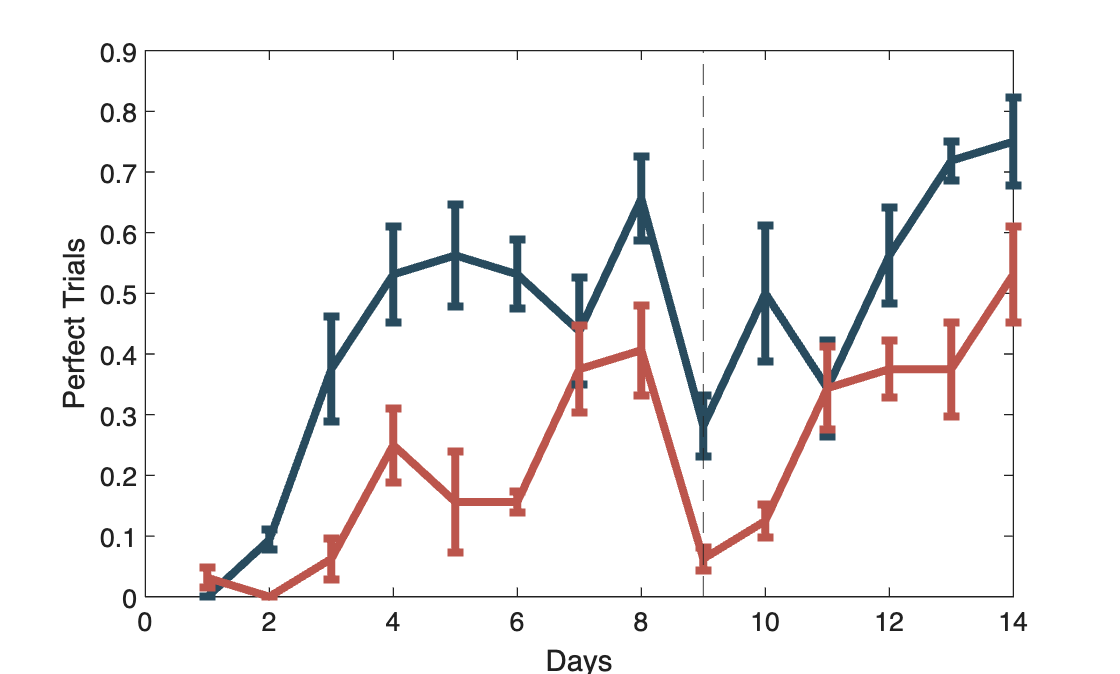

perfect_d = average_matrix(perfect_day,animals,8);
[perf_gen,perf_gen_se] = genotype(perfect_d,negative,positive);

figure
c = plot(perf_gen,'LineWidth',3);
hold on
[c(1).Color, c(2).Color] = colors{:};
xlabel('Days');
ylabel('Perfect Trials');
er = errorbar(perf_gen,perf_gen_se);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
xline(9,'--');

## Averaging to Day

%If I want a percentage I have to devide this on the total number of entries during eachc session

score_rm = average_matrix(rm_numb,animals,8);

score_wm = average_matrix(wm_numb,animals,8);

score_total = average_matrix(total_error,animals,8);
score_session = average_matrix(total_error,animals,4);

% I only have 2 Cre+ here
posthoc = average_matrix(post_hoc,2,4);
follow_up = mean(posthoc,2);
follow_up_se =std(posthoc,0,2)/sqrt(length(posthoc)); 

posthoc2 = average_matrix(post_hoc,2,8);
follow_up2 = mean(posthoc2,2);
follow_up_se2 =std(posthoc2,0,2)/sqrt(length(posthoc2)); 

% Group genotyping session; TOTAL ERROR
[gen,genotype_se] = genotype(score_total,negative,positive);

[session,session_se] = genotype(score_session,negative,positive);

% Group genotyping session; REFERENCE MEMORY ERROR
[genotype_rm,genotype_se_rm] = genotype(score_rm,negative,positive);

% Group genotyping session; REFERENCE MEMORY ERROR
[genotype_wm,genotype_se_wm] = genotype(score_wm,negative,positive);

## Trajectory Analysis of Grouped Animals

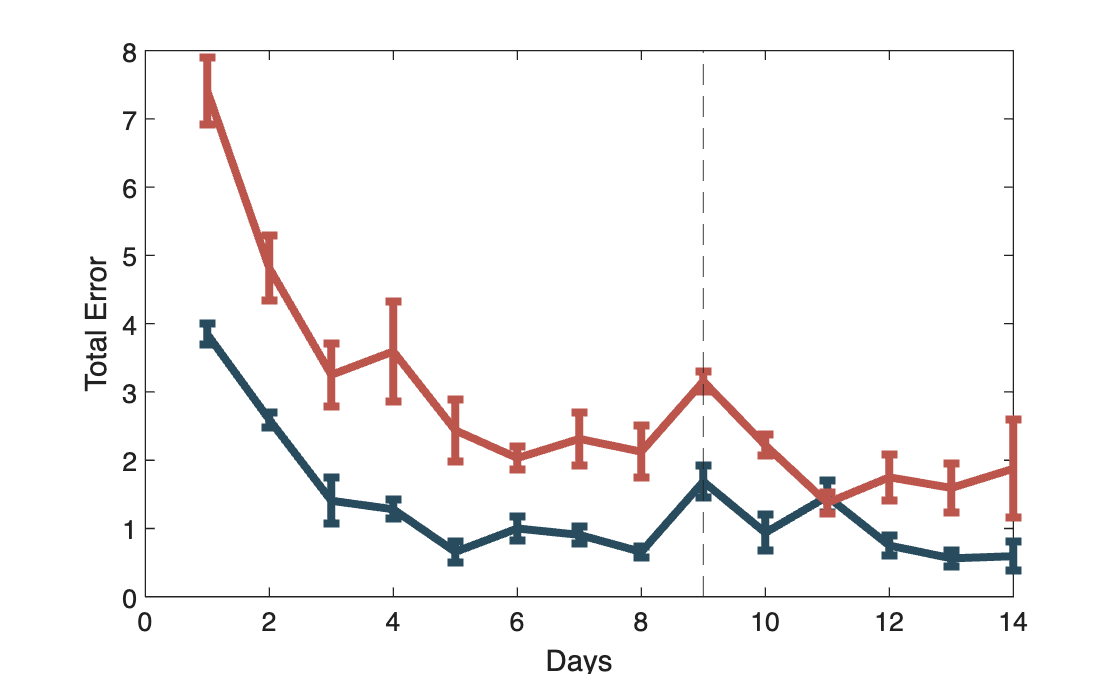

figure
c = plot(gen,'LineWidth',3);
hold on
[c(1).Color, c(2).Color] = colors{:};
xlabel('Days');
ylabel('Total Error');
er = errorbar(gen,genotype_se);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
xline(9,'--');

% Perform repeated measures ANOVA
[p,tbl,statistics] = anova2(gen(1:8,:),2,"off");
traject = multcompare(statistics,'Display','off');
tbl1 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl1 = 1×6 table
    Group A    Group B    Lower Limit      A-B      Upper Limit     P-value  
    _______    _______    ___________    _______    ___________    __________

       1          2         -2.8084      -1.9531      -1.0978      0.00075914

	Get insights using Copilot


% Perform repeated measures ANOVA
[p,tbl,statistics] = anova2(gen(9:end,:),2,"off");
traject = multcompare(statistics,'Display','off');
tbl2 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl2 = 1×6 table
    Group A    Group B    Lower Limit      A-B       Upper Limit     P-value 
    _______    _______    ___________    ________    ___________    _________

       1          2         -1.5968      -0.99479     -0.39283      0.0067738

	Get insights using Copilot


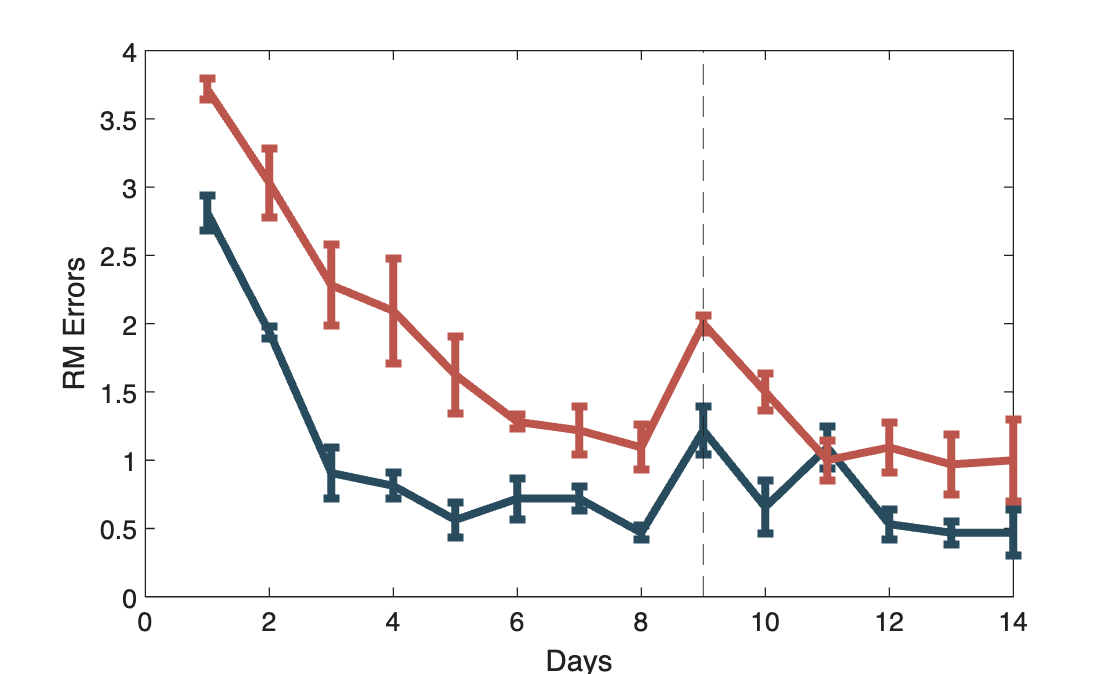


figure
c = plot(genotype_rm,'LineWidth',3);
hold on
[c(1).Color, c(2).Color] = colors{:};
xlabel('Days');
ylabel('RM Errors');
er = errorbar(genotype_rm,genotype_se_rm);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
xline(9,'--');

[p,tbl,statistics] = anova2(genotype_rm(1:8,:),2,"off");
traject = multcompare(statistics,"Display","off");
tbl1 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl1 = 1×6 table
    Group A    Group B    Lower Limit      A-B       Upper Limit     P-value  
    _______    _______    ___________    ________    ___________    __________

       1          2         -1.2792      -0.92578      -0.5724      0.00030887

	Get insights using Copilot



[p,tbl,statistics] = anova2(genotype_rm(9:end,:),2,"off");
traject = multcompare(statistics,"Display","off");
tbl2 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl2 = 1×6 table
    Group A    Group B    Lower Limit      A-B       Upper Limit    P-value 
    _______    _______    ___________    ________    ___________    ________

       1          2        -0.90613      -0.52083     -0.13554      0.016251

	Get insights using Copilot


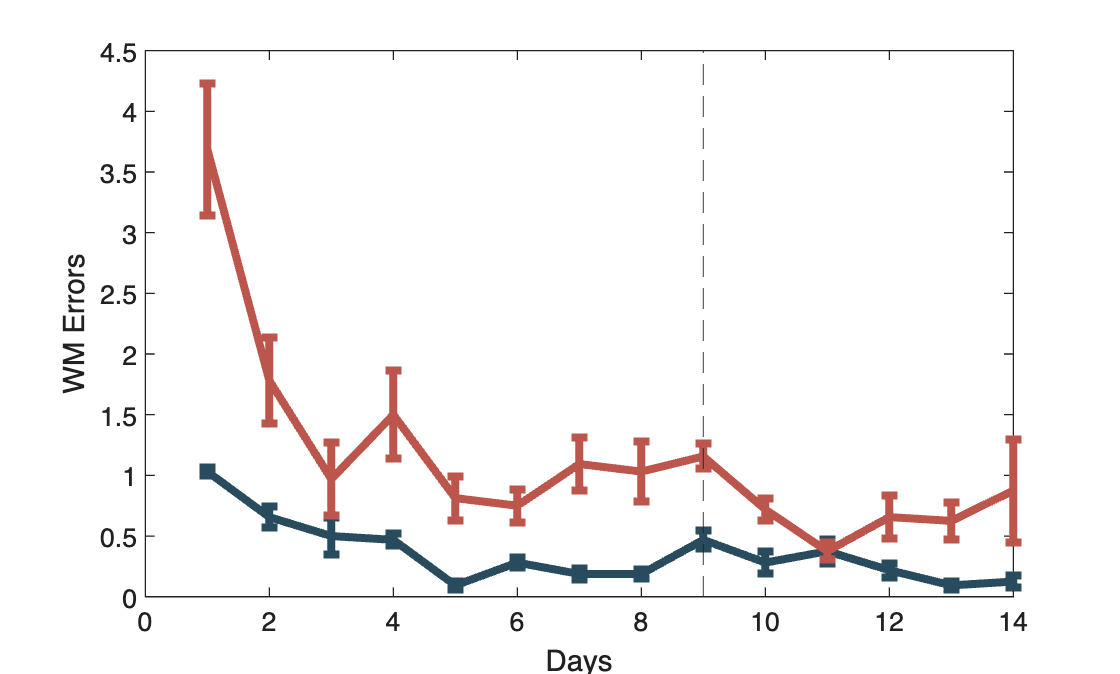


figure
c = plot(genotype_wm,'LineWidth',3);
hold on
[c(1).Color, c(2).Color] = colors{:};
xlabel('Days');
ylabel('WM Errors');
er = errorbar(genotype_wm,genotype_se_wm);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
xline(9,'--');
hold off

[p,tbl,statistics] = anova2(genotype_wm(1:8,:),2,"off");
traject = multcompare(statistics,"Display","off");

tbl1 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl1 = 1×6 table
    Group A    Group B    Lower Limit      A-B      Upper Limit     P-value 
    _______    _______    ___________    _______    ___________    _________

       1          2         -1.611       -1.0273     -0.44364      0.0036402

	Get insights using Copilot



[p,tbl,statistics] = anova2(genotype_wm(9:end,:),2,"off");
traject = multcompare(statistics,"Display","off");
tbl2 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl2 = 1×6 table
    Group A    Group B    Lower Limit      A-B       Upper Limit     P-value 
    _______    _______    ___________    ________    ___________    _________

       1          2         -0.7298      -0.47396     -0.21812      0.0039623

	Get insights using Copilot


## Plot Inter-Trial Differences

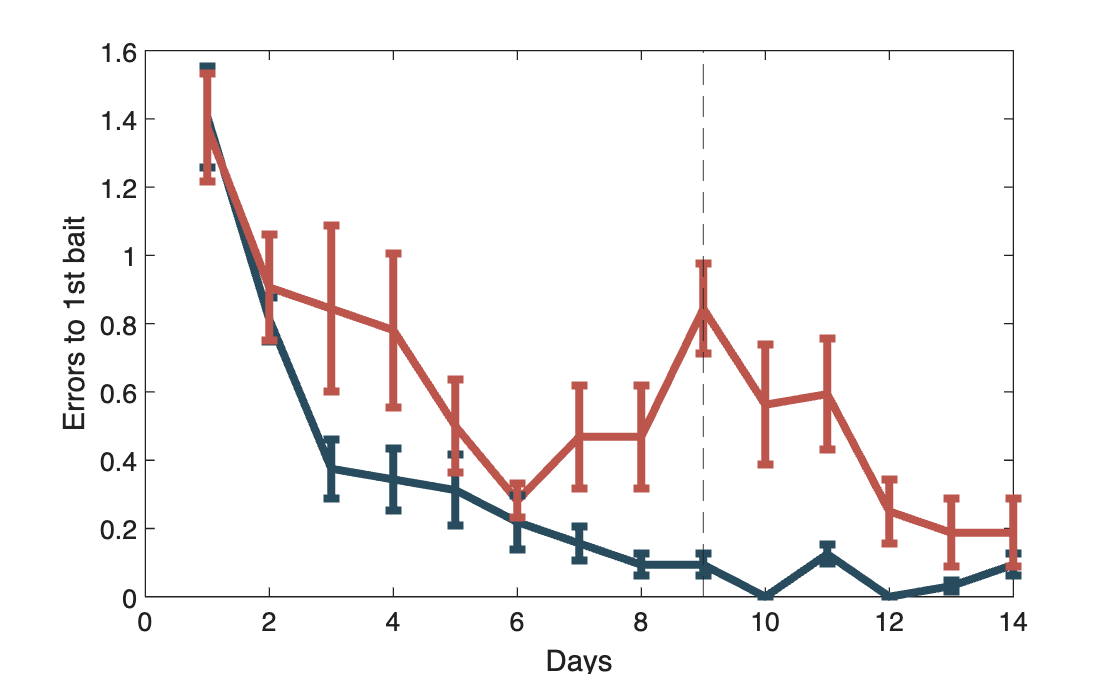

[E1_gen,E1_gen_se] = genotype(average_matrix(E1,animals,8),negative,positive);
[E2_gen,E2_gen_se] = genotype(average_matrix(E2,animals,8),negative,positive);
[E3_gen,E3_gen_se] = genotype(average_matrix(E3,animals,8),negative,positive);

figure
c = plot(E1_gen,'LineWidth',3);
hold on
[c(1).Color, c(2).Color] = colors{:};
xlabel('Days');
ylabel('Errors to 1st bait');
er = errorbar(E1_gen,E1_gen_se);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
xline(9,'--');
hold off

% Perform repeated measures ANOVA
[p,tbl,statistics] = anova2(E1_gen(1:8,:),2,"off");
traject = multcompare(statistics,'Display','off');
tbl1 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl1 = 1×6 table
    Group A    Group B    Lower Limit      A-B       Upper Limit    P-value 
    _______    _______    ___________    ________    ___________    ________

       1          2        -0.46847      -0.23828    -0.0080964     0.044054

	Get insights using Copilot


[p,tbl,statistics] = anova2(E1_gen(9:end,:),2,"off");
traject = multcompare(statistics,'Display','off');
tbl2 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl2 = 1×6 table
    Group A    Group B    Lower Limit      A-B       Upper Limit     P-value 
    _______    _______    ___________    ________    ___________    _________

       1          2        -0.57391      -0.38021     -0.18651      0.0029913

	Get insights using Copilot


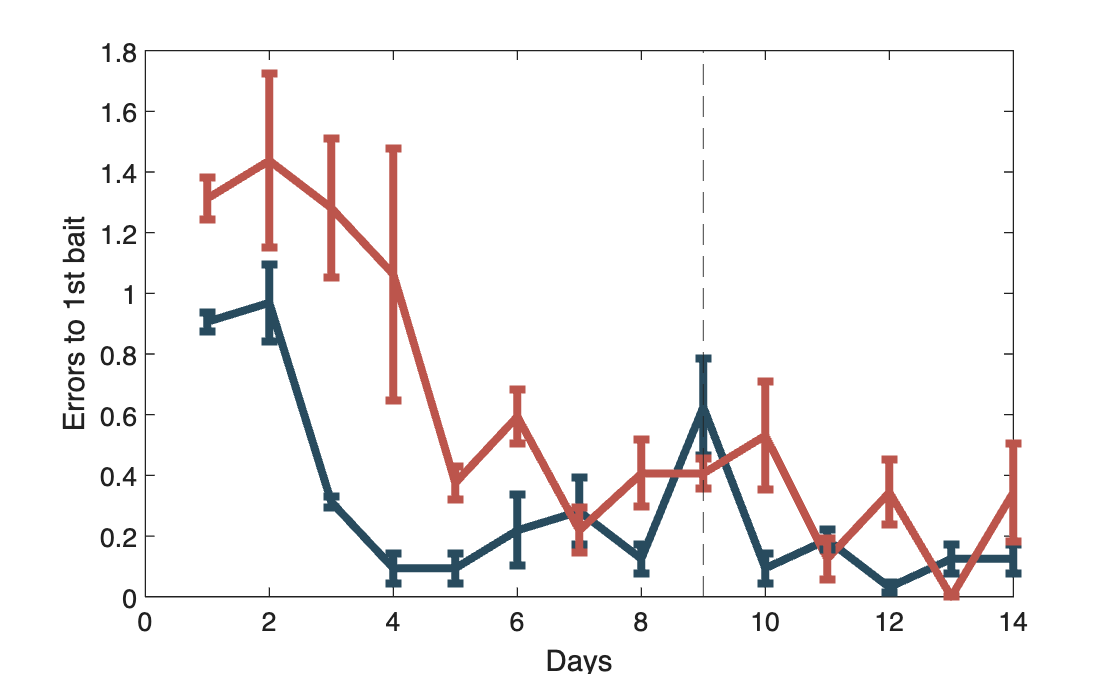


figure
c = plot(E2_gen,'LineWidth',3);
hold on
[c(1).Color, c(2).Color] = colors{:};
xlabel('Days');
ylabel('Errors to 1st bait');
er = errorbar(E2_gen,E2_gen_se);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
xline(9,'--');
hold off

% Perform repeated measures ANOVA
[p,tbl,statistics] = anova2(E2_gen(1:8,:),2,"off");
traject = multcompare(statistics,'Display','off');
tbl1 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl1 = 1×6 table
    Group A    Group B    Lower Limit      A-B       Upper Limit     P-value  
    _______    _______    ___________    ________    ___________    __________

       1          2        -0.60164      -0.46094     -0.32023      6.5808e-05

	Get insights using Copilot


[p,tbl,statistics] = anova2(E2_gen(9:end,:),2,"off");
traject = multcompare(statistics,'Display','off');
tbl2 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl2 = 1×6 table
    Group A    Group B    Lower Limit      A-B       Upper Limit    P-value
    _______    _______    ___________    ________    ___________    _______

       1          2        -0.37872      -0.09375      0.19122      0.45154

	Get insights using Copilot


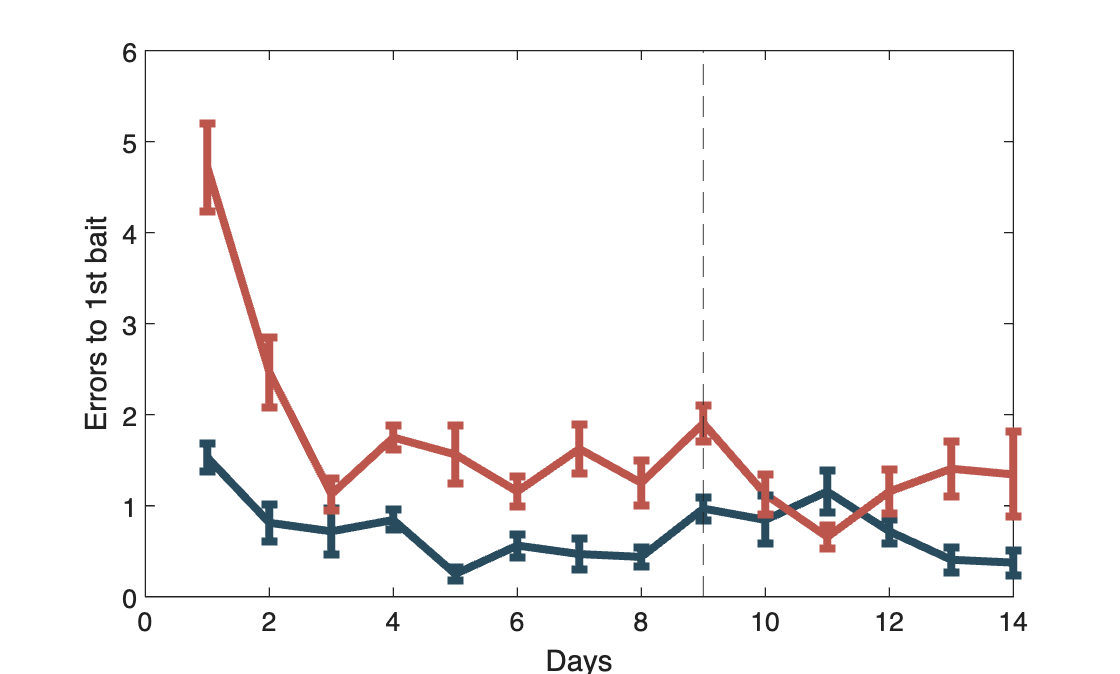


figure
c = plot(E3_gen,'LineWidth',3);
hold on
[c(1).Color, c(2).Color] = colors{:};
xlabel('Days');
ylabel('Errors to 1st bait');
er = errorbar(E3_gen,E3_gen_se);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
xline(9,'--');
hold off

% Perform repeated measures ANOVA
[p,tbl,statistics] = anova2(E3_gen(1:8,:),2,"off");
traject = multcompare(statistics,'Display','off');
tbl1 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl1 = 1×6 table
    Group A    Group B    Lower Limit      A-B      Upper Limit     P-value 
    _______    _______    ___________    _______    ___________    _________

       1          2         -1.9825      -1.2539     -0.52527      0.0041281

	Get insights using Copilot


[p,tbl,statistics] = anova2(E3_gen(9:end,:),2,"off");
traject = multcompare(statistics,'Display','off');
tbl2 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl2 = 1×6 table
    Group A    Group B    Lower Limit      A-B       Upper Limit    P-value 
    _______    _______    ___________    ________    ___________    ________

       1          2        -0.94313      -0.52083     -0.098536     0.023462

	Get insights using Copilot


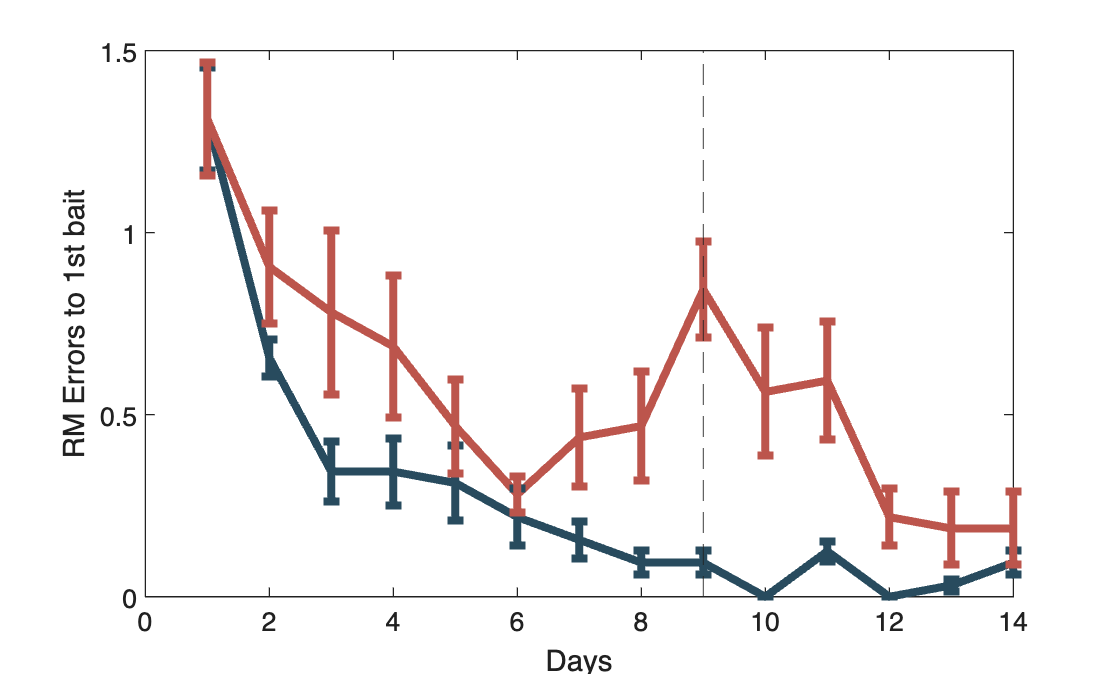

% what kind of errors
[E1rm_gen,E1rm_gen_se] = genotype(average_matrix(E1rm,animals,8),negative,positive);
[E2rm_gen,E2rm_gen_se] = genotype(average_matrix(E2rm,animals,8),negative,positive);
[E3rm_gen,E3rm_gen_se] = genotype(average_matrix(E3rm,animals,8),negative,positive);

figure
c = plot(E1rm_gen,'LineWidth',3);
hold on
[c(1).Color, c(2).Color] = colors{:};
xlabel('Days');
ylabel('RM Errors to 1st bait');
er = errorbar(E1rm_gen,E1rm_gen_se);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
xline(9,'--');
hold off

% Perform repeated measures ANOVA
[p,tbl,statistics] = anova2(E1rm_gen(1:8,:),2,"off");
traject = multcompare(statistics,'Display','off');
tbl1 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl1 = 1×6 table
    Group A    Group B    Lower Limit      A-B       Upper Limit    P-value 
    _______    _______    ___________    ________    ___________    ________

       1          2        -0.47127      -0.23828    -0.0052935     0.046073

	Get insights using Copilot



% Perform repeated measures ANOVA
[p,tbl,statistics] = anova2(E1rm_gen(9:end,:),2,"off");
traject = multcompare(statistics,'Display','off');
tbl2 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl2 = 1×6 table
    Group A    Group B    Lower Limit     A-B      Upper Limit     P-value 
    _______    _______    ___________    ______    ___________    _________

       1          2        -0.57811      -0.375     -0.17189      0.0040273

	Get insights using Copilot


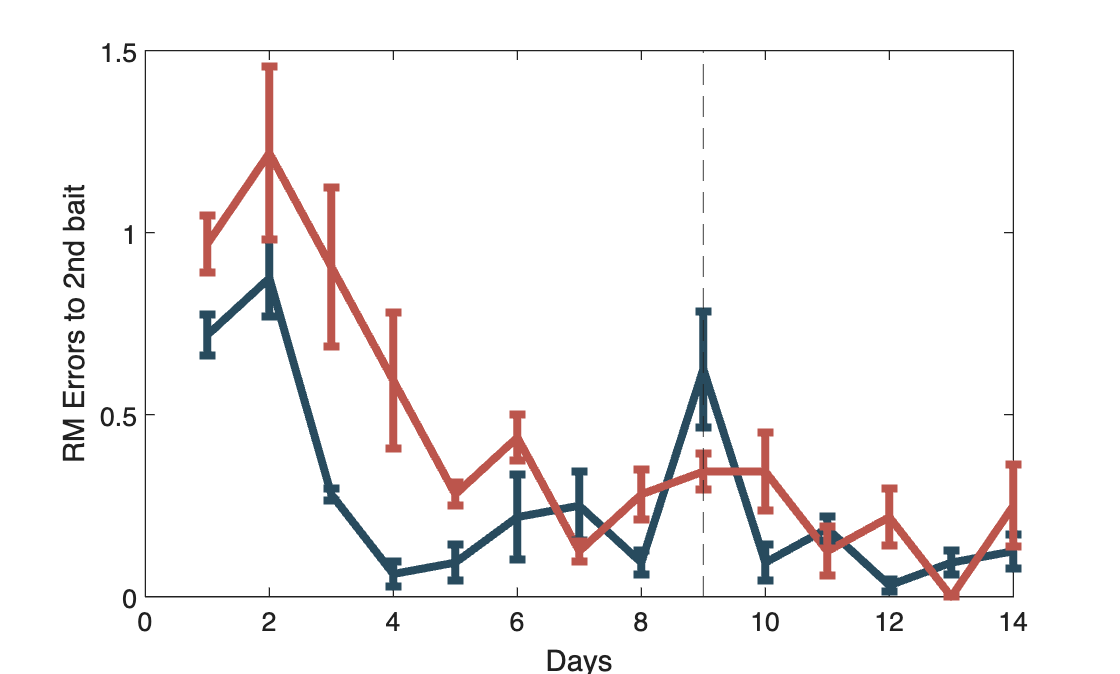

figure
c = plot(E2rm_gen,'LineWidth',3);
hold on
[c(1).Color, c(2).Color] = colors{:};
xlabel('Days');
ylabel('RM Errors to 2nd bait');
er = errorbar(E2rm_gen,E2rm_gen_se);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
xline(9,'--');
hold off

% Perform repeated measures ANOVA
[p,tbl,statistics] = anova2(E2rm_gen(1:8,:),2,"off");
traject = multcompare(statistics,'Display','off');
tbl1 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl1 = 1×6 table
    Group A    Group B    Lower Limit      A-B       Upper Limit     P-value 
    _______    _______    ___________    ________    ___________    _________

       1          2        -0.44073      -0.27734     -0.11396      0.0044536

	Get insights using Copilot



% Perform repeated measures ANOVA
[p,tbl,statistics] = anova2(E2rm_gen(9:end,:),2,"off");
traject = multcompare(statistics,'Display','off');
tbl2 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl2 = 1×6 table
    Group A    Group B    Lower Limit       A-B       Upper Limit    P-value
    _______    _______    ___________    _________    ___________    _______

       1          2        -0.27187      -0.020833      0.2302       0.84579

	Get insights using Copilot


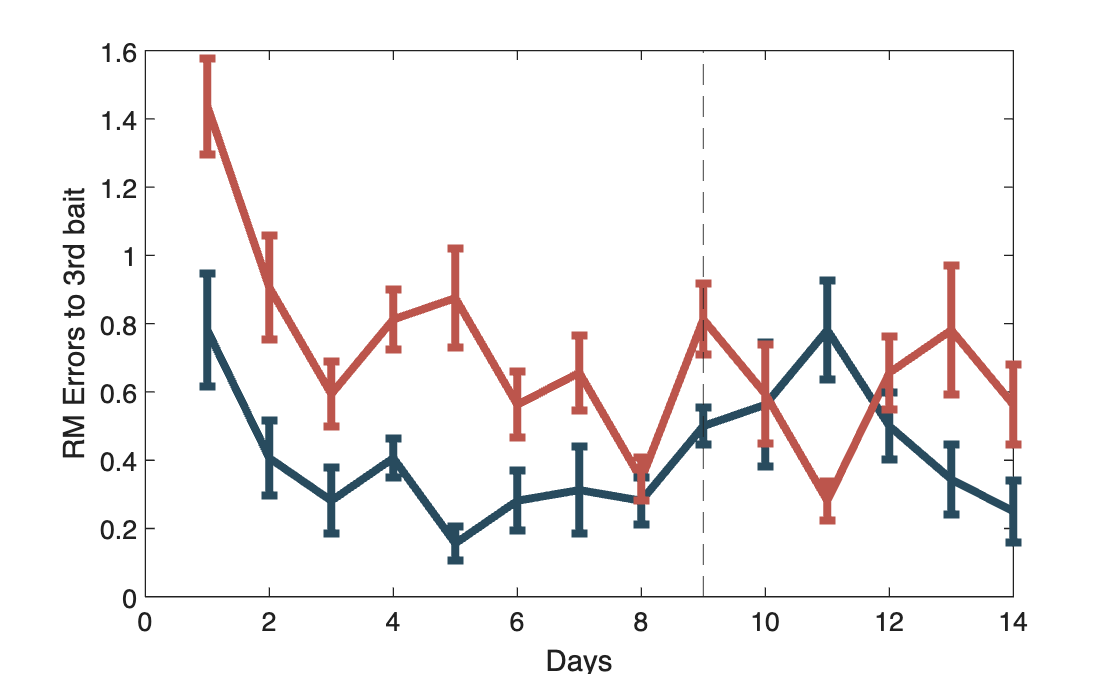

figure
c = plot(E3rm_gen,'LineWidth',3);
hold on
[c(1).Color, c(2).Color] = colors{:};
xlabel('Days');
ylabel('RM Errors to 3rd bait');
er = errorbar(E3rm_gen,E3rm_gen_se);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
xline(9,'--');
hold off

% Perform repeated measures ANOVA
[p,tbl,statistics] = anova2(E3rm_gen(1:8,:),2,"off");
traject = multcompare(statistics,'Display','off');
tbl1 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl1 = 1×6 table
    Group A    Group B    Lower Limit      A-B       Upper Limit     P-value 
    _______    _______    ___________    ________    ___________    _________

       1          2        -0.65102      -0.41016     -0.16929      0.0043765

	Get insights using Copilot



% Perform repeated measures ANOVA
[p,tbl,statistics] = anova2(E3rm_gen(9:end,:),2,"off");
traject = multcompare(statistics,'Display','off');
tbl2 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl2 = 1×6 table
    Group A    Group B    Lower Limit     A-B      Upper Limit    P-value
    _______    _______    ___________    ______    ___________    _______

       1          2        -0.35861      -0.125      0.10861      0.23833

	Get insights using Copilot


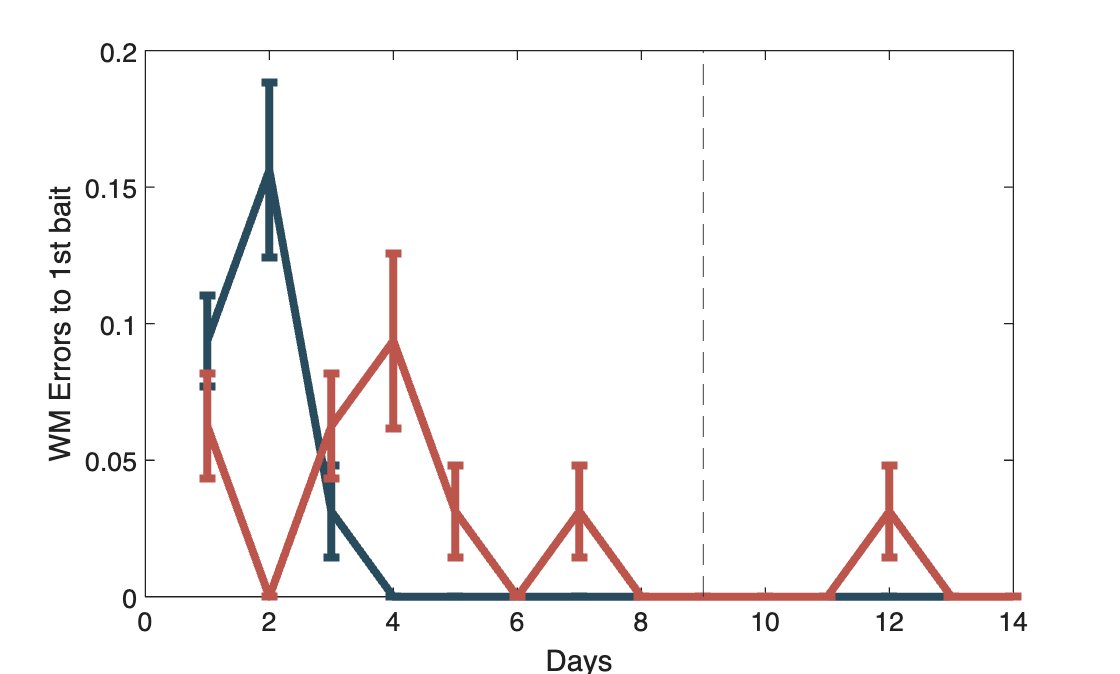

[E1wm_gen,E1wm_gen_se] = genotype(average_matrix(E1wm,animals,8),negative,positive);
[E2wm_gen,E2wm_gen_se] = genotype(average_matrix(E2wm,animals,8),negative,positive);
[E3wm_gen,E3wm_gen_se] = genotype(average_matrix(E3wm,animals,8),negative,positive);

figure
c = plot(E1wm_gen,'LineWidth',3);
hold on
[c(1).Color, c(2).Color] = colors{:};
xlabel('Days');
ylabel('WM Errors to 1st bait');
er = errorbar(E1wm_gen,E1wm_gen_se);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
xline(9,'--');
hold off

% Perform repeated measures ANOVA
[p,tbl,statistics] = anova2(E1wm_gen(1:8,:),2,"off");
traject = multcompare(statistics,'Display','off');
tbl1 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl1 = 1×6 table
    Group A    Group B    Lower Limit    A-B    Upper Limit    P-value
    _______    _______    ___________    ___    ___________    _______

       1          2        -0.031204      0      0.031204         1   

	Get insights using Copilot


% Perform repeated measures ANOVA
[p,tbl,statistics] = anova2(E1wm_gen(9:end,:),2,"off");
traject = multcompare(statistics,'Display','off');
tbl2 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl2 = 1×6 table
    Group A    Group B    Lower Limit       A-B        Upper Limit    P-value
    _______    _______    ___________    __________    ___________    _______

       1          2        -0.017953     -0.0052083     0.007536      0.35592

	Get insights using Copilot


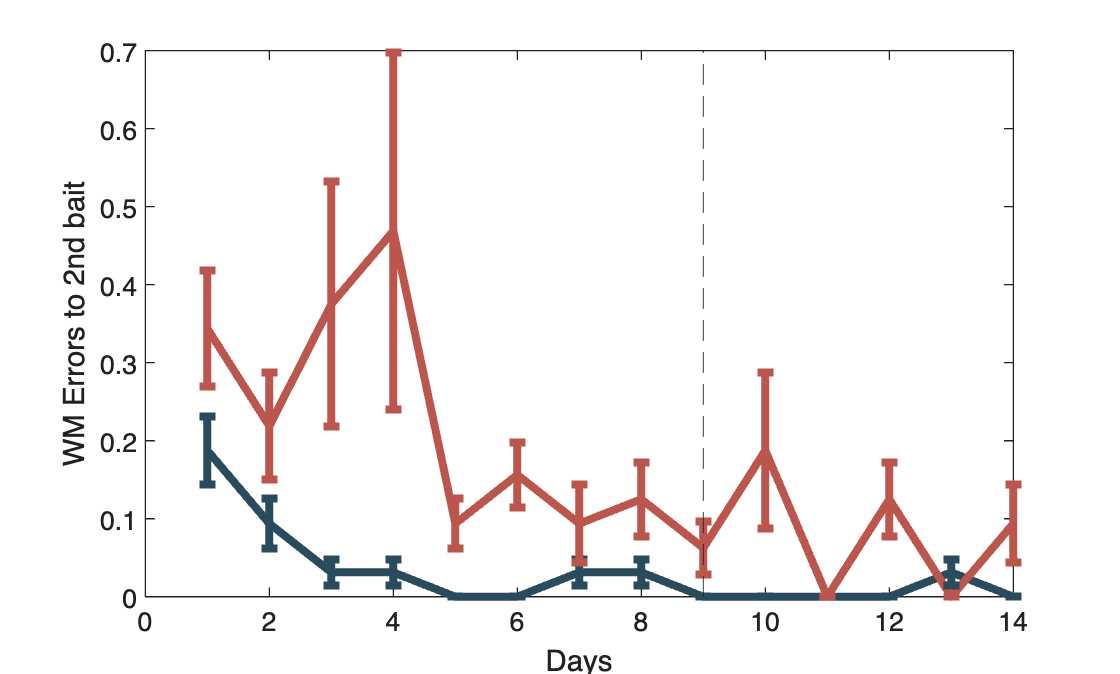

figure
c = plot(E2wm_gen,'LineWidth',3);
hold on
[c(1).Color, c(2).Color] = colors{:};
xlabel('Days');
ylabel('WM Errors to 2nd bait');
er = errorbar(E2wm_gen,E2wm_gen_se);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
xline(9,'--');
hold off

% Perform repeated measures ANOVA
[p,tbl,statistics] = anova2(E2wm_gen(1:8,:),2,"off");
traject = multcompare(statistics,'Display','off');
tbl1 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl1 = 1×6 table
    Group A    Group B    Lower Limit      A-B       Upper Limit     P-value  
    _______    _______    ___________    ________    ___________    __________

       1          2        -0.23985      -0.18359     -0.12734      6.7578e-05

	Get insights using Copilot


% Perform repeated measures ANOVA
[p,tbl,statistics] = anova2(E2wm_gen(9:end,:),2,"off");
traject = multcompare(statistics,'Display','off');
tbl2 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl2 = 1×6 table
    Group A    Group B    Lower Limit       A-B       Upper Limit    P-value 
    _______    _______    ___________    _________    ___________    ________

       1          2        -0.15551      -0.072917     0.009676      0.074051

	Get insights using Copilot


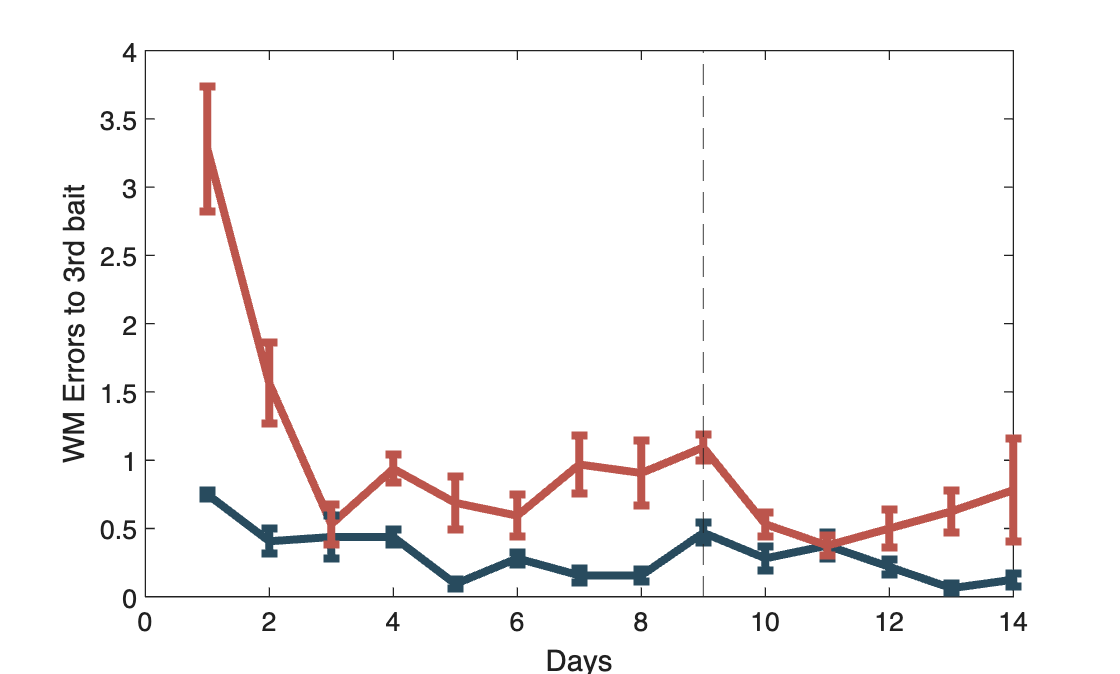

figure
c = plot(E3wm_gen,'LineWidth',3);
hold on
[c(1).Color, c(2).Color] = colors{:};
xlabel('Days');
ylabel('WM Errors to 3rd bait');
er = errorbar(E3wm_gen,E3wm_gen_se);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
xline(9,'--');
hold off

% Perform repeated measures ANOVA
[p,tbl,statistics] = anova2(E3wm_gen(1:8,:),2,"off");
traject = multcompare(statistics,'Display','off');
tbl1 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl1 = 1×6 table
    Group A    Group B    Lower Limit      A-B       Upper Limit     P-value 
    _______    _______    ___________    ________    ___________    _________

       1          2         -1.3662      -0.84375      -0.3213      0.0058366

	Get insights using Copilot


% Perform repeated measures ANOVA
[p,tbl,statistics] = anova2(E3wm_gen(9:end,:),2,"off");
traject = multcompare(statistics,'Display','off');
tbl2 = array2table(traject,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl2 = 1×6 table
    Group A    Group B    Lower Limit      A-B       Upper Limit    P-value 
    _______    _______    ___________    ________    ___________    ________

       1          2        -0.66011      -0.39583     -0.13156      0.010516

	Get insights using Copilot


## Save Variables

% save("HabituationData.mat", "entry_raw","speed_open_field","open_field_move", "occupancy");
% save("SpeedRAM.mat", "entry_raw_comp","all_paths","all_paths_errors","speed_raw","speed_avr","total_error","trial_length","distance_raw");
% save("RAMdata.mat",'Data','entry_raw_comp','negative','positive', 'failed_injection', 'total_error','E1','E2','E3','correct','incorrect','all_paths');

% % Compile data for Rej
% genotypes = zeros(1,animals);
% genotypes(negative) = 1;
% genotypes(positive) = 2;
% genotypes(failed_injection) = 3;
% zones = entry_raw_comp;
% all_trajectories = all_paths{6:end,:};
% save("E:\Ingvild\Analysis\Figures\Ingvild\Behavior\Data\RAMbehavior.mat", 'Data', 'zones', 'genotypes', 'all_trajectories','E1','E2','E3');